# Registering Medical Volumes

Registering medical volumes is a common tasks for both clinical applications and research studies. This script provides a workflow you can use for registering medical volumes. If you need to register medical images, continue through the course to learn how to use the Registration Estimator App.

## Import the Data

Use the controls below to select the T1_3T_2018 and the T1_7T_2020 folders located inside the MRI Images. They are inside the Data folder provided with the course files.

Run this section after selecting for image folders.

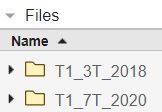

vol3TFolder = "C:\Users\Banuka\Desktop\Medical Imaging\Medical Image Processing\Data\MRI Images\T1_3T_2018";
vol7TFolder = "C:\Users\Banuka\Desktop\Medical Imaging\Medical Image Processing\Data\MRI Images\T1_7T_2020";

Import the data using the `medicalVolume` function.

vol3T = medicalVolume(vol3TFolder)

vol3T =   medicalVolume with properties:

                  Voxels: [192×192×128 int16]
          VolumeGeometry: [1×1 medicalref3d]
            SpatialUnits: "mm"
             Orientation: "coronal"
            VoxelSpacing: [2.6042 2.6042 3.1000]
            NormalVector: [0 1 0]
        NumCoronalSlices: 128
       NumSagittalSlices: 192
     NumTransverseSlices: 192
            PlaneMapping: ["sagittal"    "transverse"    "coronal"]
    DataDimensionMeaning: ["left"    "inferior"    "posterior"]
                Modality: "MR"
           WindowCenters: [128×1 double]
            WindowWidths: [128×1 double]


vol7T = medicalVolume(vol7TFolder)

vol7T =   medicalVolume with properties:

                  Voxels: [128×128×96 int16]
          VolumeGeometry: [1×1 medicalref3d]
            SpatialUnits: "mm"
             Orientation: "sagittal"
            VoxelSpacing: [2 2 2]
            NormalVector: [-1 0 0]
        NumCoronalSlices: 128
       NumSagittalSlices: 96
     NumTransverseSlices: 128
            PlaneMapping: ["coronal"    "transverse"    "sagittal"]
    DataDimensionMeaning: ["posterior"    "inferior"    "left"]
                Modality: "MR"
           WindowCenters: [96×1 double]
            WindowWidths: [96×1 double]


### Examine the metadata

Look at the metadata properties above for each volume. The resolution and plane mapping are different. Registration works best when the geometries of the volumes are the same.

### Visualize the volumes

Notice that the 7 Tesla volume covers a smaller portion of the body while the 3 Tesla volume includes the neck and shoulders.

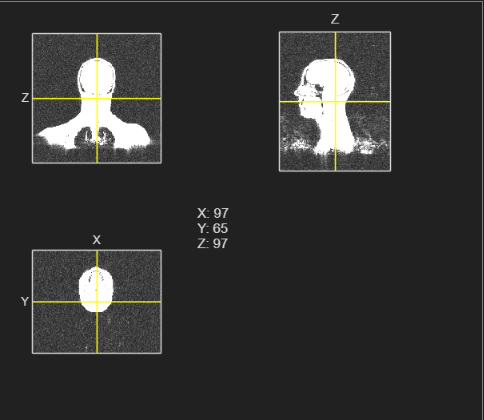

orthosliceViewer(vol3T)

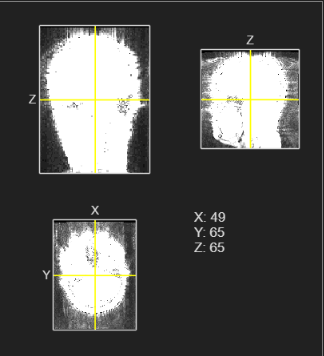

orthosliceViewer(vol7T)

## Resample One Volume

It is usually necessary to ensure your volumes have the same plane mapping and voxel spacing before registration. If they do not, use the `resample` function to resample the voxels to the same geometry. Here, we resample the 3 Tesla volume to the geometry of the 7 Tesla. Often the choice of which volume to resample doesn't matter. In this example, resampling the 3 Tesla volume helps because it removes the neck and shoulders so that both volumes will only include the head.

resampled3T = resample(vol3T, vol7T.VolumeGeometry)

resampled3T =   medicalVolume with properties:

                  Voxels: [128×128×96 int16]
          VolumeGeometry: [1×1 medicalref3d]
            SpatialUnits: "mm"
             Orientation: "sagittal"
            VoxelSpacing: [2 2 2]
            NormalVector: [-1 0 0]
        NumCoronalSlices: 128
       NumSagittalSlices: 96
     NumTransverseSlices: 128
            PlaneMapping: ["coronal"    "transverse"    "sagittal"]
    DataDimensionMeaning: ["posterior"    "inferior"    "left"]
                Modality: "MR"
           WindowCenters: []
            WindowWidths: []


### **Visualize the resampled volume**

Visualize a slice of the volumes you will register. The volumes are not aligned, but the resampling has brought them much closer together. You can see that there is both rotation and translation between the two images. Less obvious is that there is also scale, which is usually the case the images are acquired at different resolutions. This means you'll need a similarity transformation.

Because the resampled 3 Tesla volume is better positioned, we'll use it as the fixed volume and the 7 Tesla volume as the moving volume for registration.

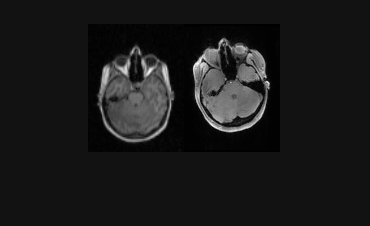

img1 = extractSlice(resampled3T, 64, "transverse");
img2 = extractSlice(vol7T, 64, "transverse");
imshowpair(img1, img2, "montage")

## Register the Volumes

To use the `imregister` function, you must create an `optimizer` and a `metric` with the `imregconfig` function. These objects include properties you can adjust if necessary to improve the registration. The default settings are a good starting point and often work well. Use the `multimodal` option because the images were acquired with very different machines.

The code below generates a new 3D array, `newVoxels` that is 7 Tesla volume registered to the resampled 3 Tesla volume.

[optimizer,metric] = imregconfig("multimodal");
newVoxels = imregister(vol7T.Voxels, resampled3T.Voxels, "similarity", optimizer, metric);

### Create a new volume with the registered data

The `imregister` does not create a `medicalVolume` object, but the metadata associate with the volume is important. Create a new `medicalVolume` that is a copy of the original. Then, replace the `Voxels` property with the new registered voxels.

registered7T = vol7T;
registered7T.Voxels = newVoxels;

## **View results**

Visualization is an important part of evaluating your results. Use the controls below to compare slices in different planes. The volumes are well aligned!

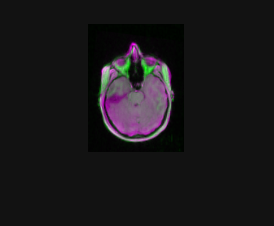

sliceNum = 65;
plane = "transverse";
imgResampled3T = extractSlice(resampled3T, sliceNum, plane);
img7Treg = extractSlice(registered7T, sliceNum, plane);
imshowpair(imgResampled3T, img7Treg)

*Copyright 2024 The MathWorks, Inc.*